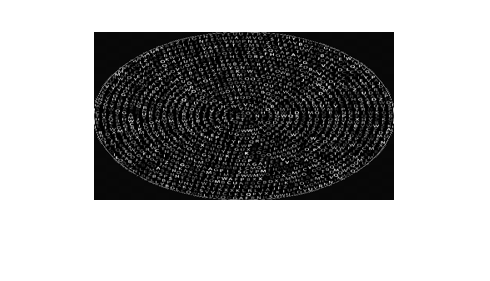

I = imread('img1.png');
Y = imread('img2.jpg');
I = imresize(I,[168,300]);
imshow(I)

size(I)

ans =    168   300


.

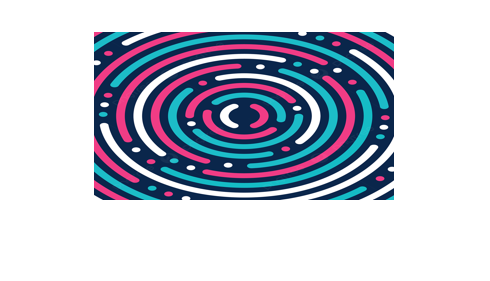

Y = imresize(Y,[168,300]);
imshow(Y)

size(Y)

ans =    168   300     3


Y=Y(:,:,1)

Y = 168×300 uint8 matrix
   240   240   240   240   240   245   249   201    82     7    10    10    10    10    10    10    10    10    10    10    16    25    28    28    28    28    28    28    28    28    28    28    29    26    20    11    10    10    10    10    10    10    10    10    10     5     0    14    68   159
   240   240   240   243   250   210    99    13     2    10    10    10    10    10    10    10    10    10    16    24    28    29    28    28    28    28    28    28    28    28    28    25    17    11     9    10    10    10    10    10    10    10     9     2     3    43   127   214   254   255
   240   241   250   226   124    23     0     8    10    10    10    10    10    10    10    10    16    24    28    28    28    28    28    28    28    28    28    28    28    23    15    10     9    10    10    10    10    10    10    10     6     0    14    78   174   243   255   255   255   255
   248   240   152    37     0     8    12    11    10    10    10    10

size(Y)

ans =    168   300


.

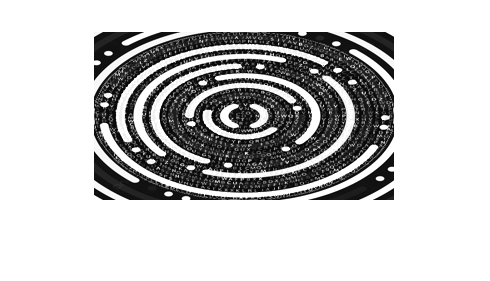

% Adding two images
ImAdd = imadd(I,Y);
imshow(ImAdd)

.

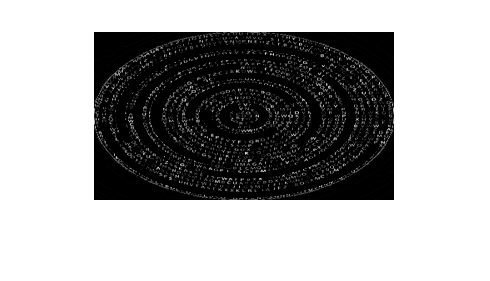

% Subtracting two images
ImSub = imsubtract(I,Y);
imshow(ImSub)

.

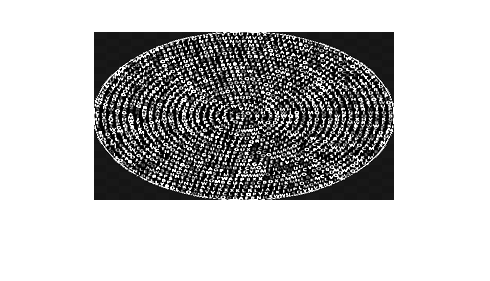

% Multiplying an image with a scalar value
ImMul = immultiply(I,3);
imshow(ImMul)

.

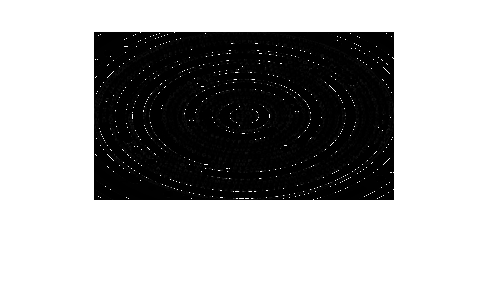

% Dividing one image by another
ImDiv = imdivide(I,Y);
imshow(ImDiv)

.

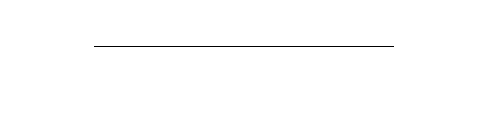

% min values of pixels
minInt = min(I);
imshow(minInt)

.

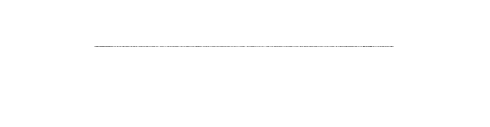

% max values of pixels
maxInt = max(I);
imshow(maxInt)

.

% Contrast calculation
ImContr = maxInt - minInt;
imshow(ImContr)

.

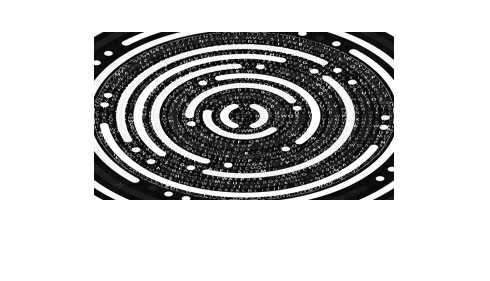

ImU = bitor(I,Y);
imshow(ImU)

.

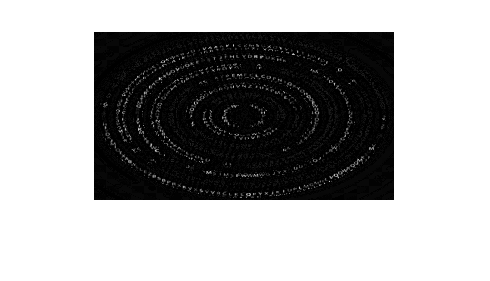

ImI = bitand(I,Y);
imshow(ImI)

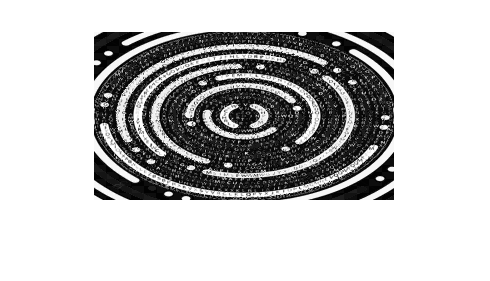

ImX = bitxor(I,Y);
imshow(ImX)

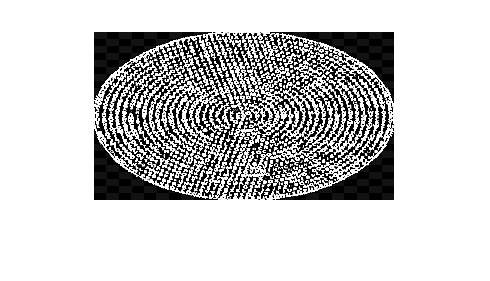

% contrast stretching with median value as threshold value
ImMed = median(I);
contStretch1 = imadjust(I,stretchlim(ImMed),[]);
imshow(contStretch1)

% contrast stretching with mean value as threshold value
ImAvg = mean(I);
contStretch2 = imadjust(I,stretchlim(ImAvg),[]);
imshow(contStretch2)

% Converting image to grayscale
%I = rgb2gray(I);
I=ind2rgb(I)

Not enough input arguments.

Error in ind2rgb (line 17)
    r = matlab.images.internal.ind2rgb(a, cm);

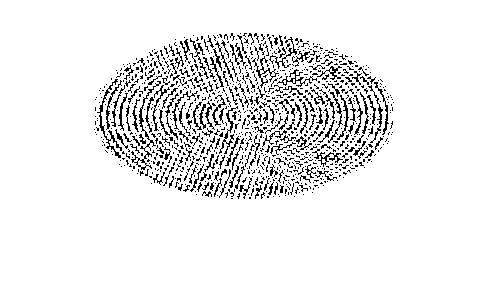

imshow(I)

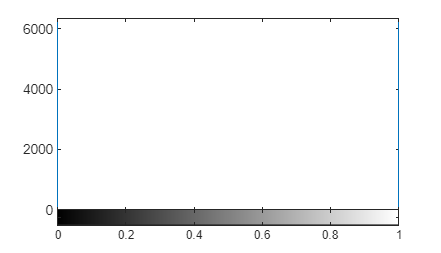

% plotting histogram
imhist(I)

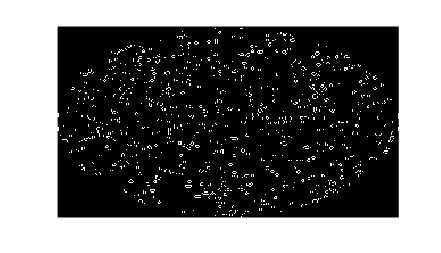

% edge detection
edgedetect = edge(I,'sobel');
imshow(edgedetect)

% Smoothing the image
Imblur1 = imgaussfilt(I,2);
Imblur2 = imgaussfilt(I,6);
imshow(Imblur1)

imshow(Imblur2)
I=double(I);
tot=0;
[a,b]=size(I);
y=zeros(a,b);
for i=1:a
 for j=1:b
 y(i,j)=0;
 end
end
for i=1:a
 for j=1:b
 tot=tot+I(i,j);
 end
end
tot

tot = 1398007

c= a*b

c = 50400

thr=tot/(a*b)

thr = 27.7382

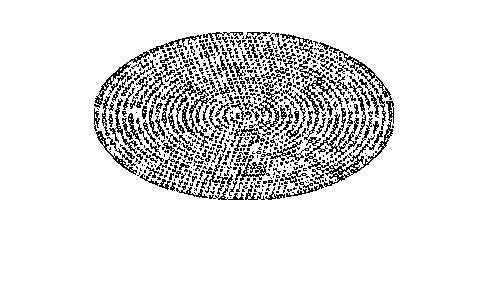

for i=1:a
 for j=1:b
 if I(i,j) > thr
 y(i,j)=0;
 else
 y(i,j)=1;
 end
 end
end
figure;
imshow(y);

% Histogram (own code)
a=imread('img1.png');
im2gray(a)
%Gray_Image=rgb2gray(a);

Error using rgb2gray>parse_inputs
MAP must be a m x 3 array. Use im2gray for RGB and grayscale images.

Error in rgb2gray (line 51)
isRGB = parse_inputs(X);

[c,d]=size(Gray_Image);
img_hist = zeros(1,256);
x = c; y=d; 
7
for i = 1:x % Rows of Input Image
 for j = 1:y % Colms of input image
 img_hist(Gray_Image(i,j,1)+1) = img_hist(Gray_Image(i,j,1)+1)+1; %Bin Increment for occurrence
 end
end
figure %Plotting the Histogram
stem(0:255, img_hist); 
grid on;
ylabel('No of Pixels');
xlabel('GrayScale Intensity Levels'); 
title('Image Histogram without Using Built-in Function');